%% Digit recognition from spoken recordings using DTW

% Generate vector 'utterances': 300 cells of Mx13 matrixes
paths = 'Final_digits/Final_digits/';
utterances = cell(1,300); 
files = dir([paths,'*.mat']);

% Get the 300 test utterances
for spokenDigits = 1 : 300
    T = load([paths, files(spokenDigits).name ]); % Test Utterance
    % M X 13 matrix, T
    % M = number of frames that utterance has and 13 is dimension of each frame.
    T = squeeze(T.feat); 
    % Save out 62x13 matrix
    utterances(spokenDigits) = {T};
end
clearvars T path spokenDigits

% For each T (columns), you will have 299 costs (rows)
allignment_costs= zeros(299,300); 

for spokenDigits = 1 : 300
    T = cell2mat(utterances(:, spokenDigits));
    M = size(T,1);
    for ref_utterances = 1 : 300
        if spokenDigits ~= ref_utterances
            % Calculate allignment cost between T and R (one number):
            R = cell2mat(utterances(:, ref_utterances));
            N = size(R,1);
            
            % Dissimilarity Matrix
            S = pdist2(T,R);
            
            % Compute accumulated DTW matrix (D) from the above dissimilarity matrix
            D = zeros(size(S));
            all_paths = cell(size(D));
            for row = 1 : M
                for col = 1 : N
                    % cumulative value D(m,n) = S(m,n) + min( D(m-1,n), D(m,n-1), D(m-1,n-1) )
                    if row>1 && col>1
                        above = D(row-1, col);
                        left = D(row, col-1); 
                        diag = D(row-1, col-1); 
                        [MIN, IDX] = min([above, left, diag]);
                        if IDX==1
                            % came from ABOVE: cell(row-1, col)
                            all_paths{row,col} = [row-1, col];
                            D(row,col) = S(row,col) + MIN;
                        elseif IDX==2
                            all_paths{row,col} = [row, col-1];
                            D(row,col) = S(row,col) + MIN;
                        else
                            all_paths{row,col} = [row-1, col-1];
                            D(row,col) = S(row,col) + MIN;
                        end
                        
                    elseif row==1 && col>1
                        % came from LEFT: cell(row, col-1)
                        all_paths{row,col} = [row, col-1];
                        D(row,col) = S(row,col);
                        
                    elseif row>1 && col==1 
                        % came from ABOVE: cell(row-1, col)
                        all_paths{row,col} = [row-1, col];
                        D(row,col) = S(row,col);
                        
                    else 
                        D(row,col) = S(row,col);
                        all_paths{row,col} = [0,0];
                    end
                end
            end
            
            % follow optimal path and calculate min_cost
            x=M; y=N;
            min_cost = 0;
            opt_path = {};
            count = 0;
            while x>1 || y>1
                min_cost = min_cost + S(x,y);
                % update x and y to min path
                x = all_paths{x,y}(1);
                y = all_paths{x,y}(2); 
                opt_path{count+1} = [x,y];
                count = count + 1;
            end
            % normalized cost
            allignment_costs(ref_utterances,spokenDigits) = min_cost / count;
        
        else 
            continue
        end
        
    end
end

% So for each utterance T (column in 'allignment_costs'), theres 299 "cost allignment" values (rows). 
% Sort them and take least 29 values (because you have 29 utterances of same digit). 
[sorted,IDXs] = mink(allignment_costs, 30);
crop_sort = sorted(2:30, :);
crop_IDXs = IDXs(2:30, :);

% Now, check if the utterances corresponding to those 29 values are of same digit 
acc = zeros(29,300);
for Ts = 1 : 300
    T_digit = str2double(files(Ts).name(1));
    for Ns = 1 : 29
        N_digit = str2double(files(crop_IDXs(Ns,Ts)).name(1));
        if T_digit == N_digit
            acc(Ns,Ts) = 1;
        else
            acc(Ns,Ts) = 0;
        end 
    end
end

% Compute accuracy for each digit.
digit_acc = zeros(1,10);
count = 1;
for digit = 1:30:300 % ends at 271
    digit_acc(count) = sum(acc(:, digit : digit+29), 'all') / (29*30);
    dig = count-1;
    disp("Accuracy for digit '" + dig + "' is " + digit_acc(count));
    count = count + 1;
end

Accuracy for digit '0' is 0.2931
Accuracy for digit '1' is 0.34943
Accuracy for digit '2' is 0.26667
Accuracy for digit '3' is 0.25632
Accuracy for digit '4' is 0.35977
Accuracy for digit '5' is 0.41149
Accuracy for digit '6' is 0.35057
Accuracy for digit '7' is 0.39655
Accuracy for digit '8' is 0.48276
Accuracy for digit '9' is 0.29425


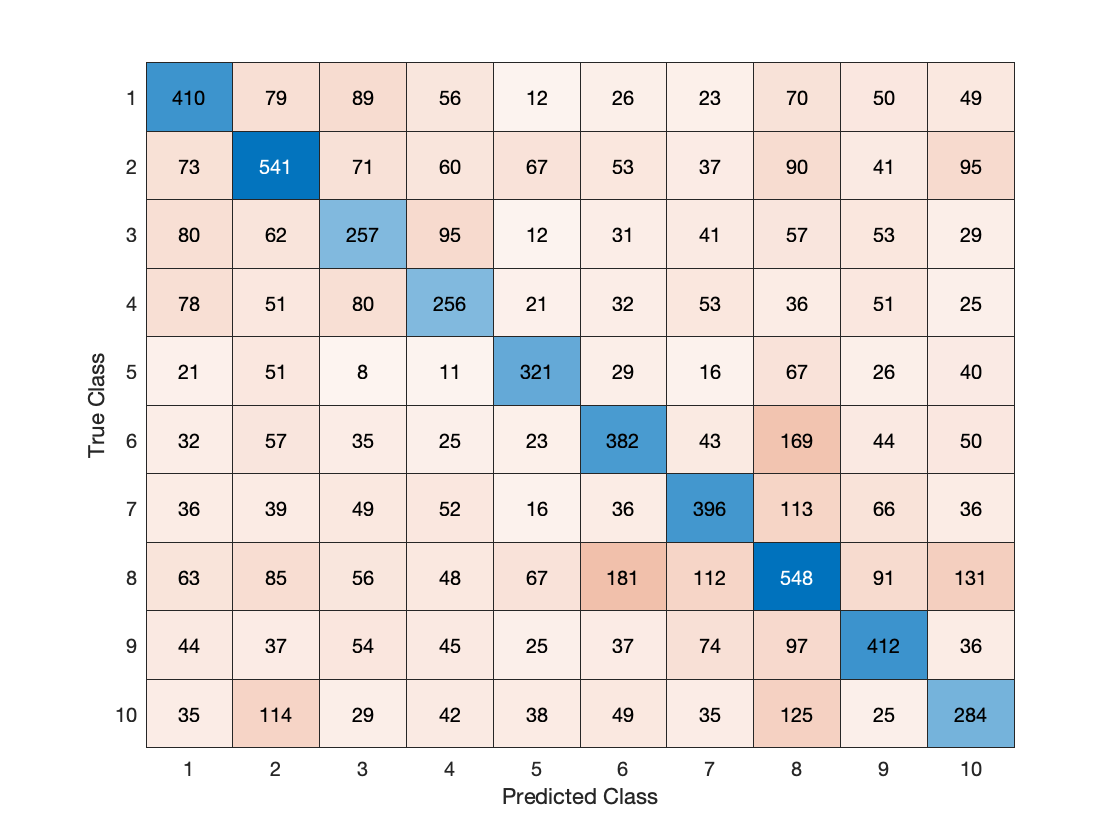

% Plot confusion matrix
ground_truth = ones(29,300);
for i = 1 : 29
    for j = 1 : 300
        ground_truth(i,j) = str2double(files( crop_IDXs(i,j) ).name(1));
    end
end

predicted = ones(29,300);
for i = 1 : 29
    for j = 1 : 300
        predicted(i,j) = str2double(files( IDXs(i,j) ).name(1));
    end
end

C = confusionmat( reshape(ground_truth, [8700 1]), reshape(predicted, [8700 1]));

confusionchart(C)

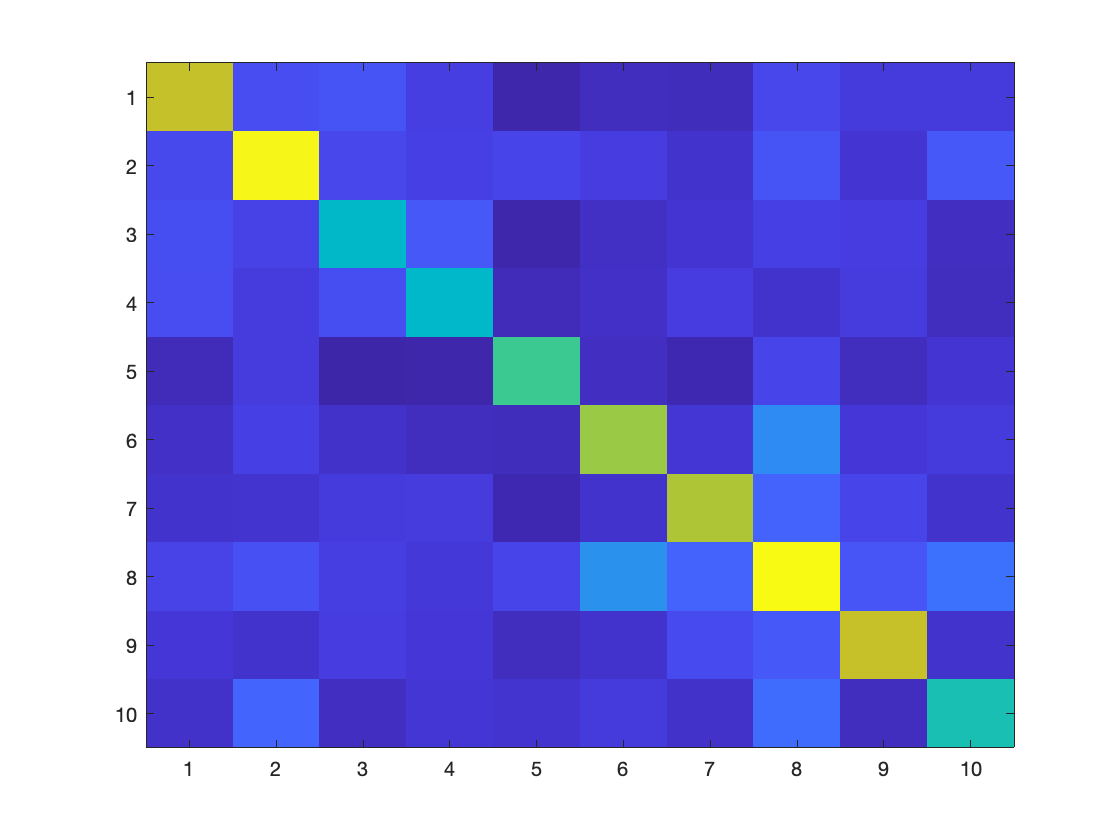

imagesc(C)